# **Antenna Theory-HW7-Q2-MOM**

### ** Soroush Mesforush Mashhad - 810198472**

w = 5;
N = 50;
M = 50;
delta_x  = 2*w/N;
X = zeros(1,N);
for i=1:length(X)
    X(i) = -w + (w/N) + (2*w/N)*(i-1);
end

L = zeros(M,N);
for n=1 : N
    for m=1: M
        L(m,n) = -delta_x/(2*pi)*((abs(m-n)+(1/2))*(log((abs(m-n)+(delta_x/2)))) - (m-n-1/2)*(log(delta_x*(abs(m-n-1/2)) )-1));
    end
end

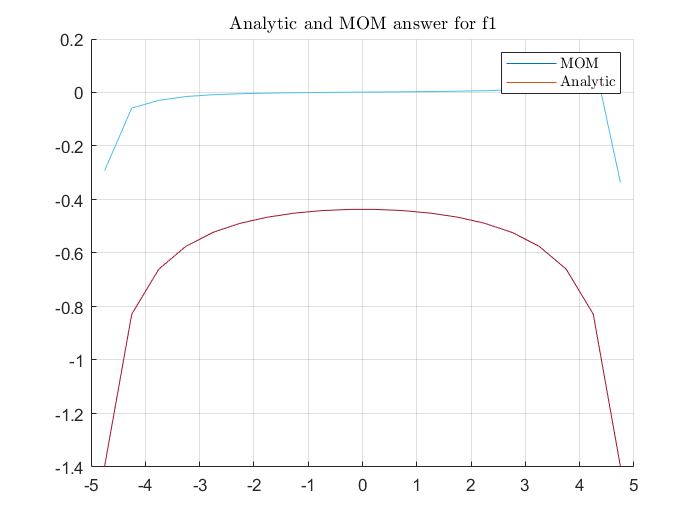

U1 = 2./(w*log(2/w)*sqrt(1-(X/w).^2));
B1 = ones(N);
alphan1 = inv(L)*B1;

figure
hold on
plot(X, alphan1)
plot(X, U1)
grid on
title('Analytic and MOM answer for f1','Interpreter','latex')
legend('MOM','Analytic','Interpreter','latex')

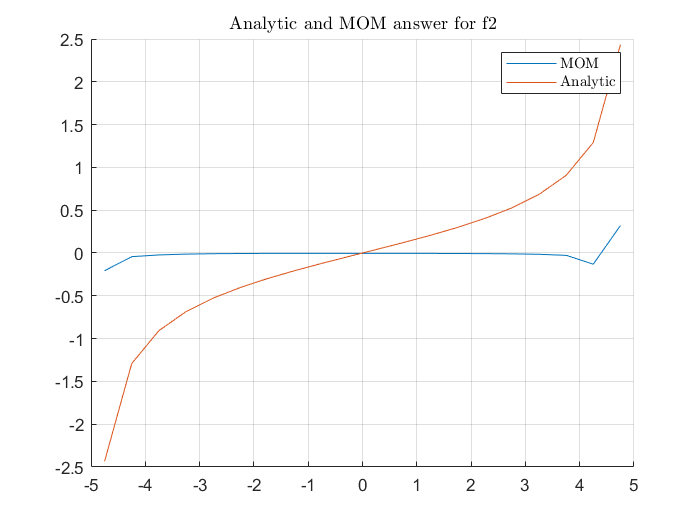

U2 = 2./w*(X/w)*2./(sqrt(1-(X/w).^2));
B2 = X/w;
alphan2 = inv(L)*B2';
figure
hold on
plot(X, alphan2)
plot(X, U2)
grid on
title('Analytic and MOM answer for f2','Interpreter','latex')
legend('MOM','Analytic','Interpreter','latex')